# Chapter 3 - Statistical experiments and tests of significance

以下は、「データサイエンスのための統計学入門」（Peter Bruce, Andrew Bruce、原題 Practical Statistics for Data Scientists）の第3章：統計実験と有意差検定を MATLAB で実行した例です。

もともとの R コードはこちら（[GitHub](https://github.com/andrewgbruce/statistics-for-data-scientists)）にあり、データも著者によって [Google Drive](https://drive.google.com/drive/folders/0B98qpkK5EJemYnJ1ajA1ZVJwMzg) もしくは [Dropbox](https://www.dropbox.com/sh/clb5aiswr7ar0ci/AABBNwTcTNey2ipoSw_kH5gra?dl=0) から入手可能です。

### 実行環境

- MATLAB R2020a

- Statistics and Machine Learning Toolbox

## 3.2.2 例: Web粘着性

**箱ひげ図と平均値**

2つのWebページのうち、どちらの方が売上に寄与するか調べるケースです。

変数名を付けてデータの読み込む場合は `readtable` 関数（[doc](https://jp.mathworks.com/help/matlab/ref/readtable.html)）、箱ひげ図にはboxplot関数（[doc](https://jp.mathworks.com/help/stats/boxplot.html)）が便利です。

各ページのセッション時間を箱ひげ図でプロット。

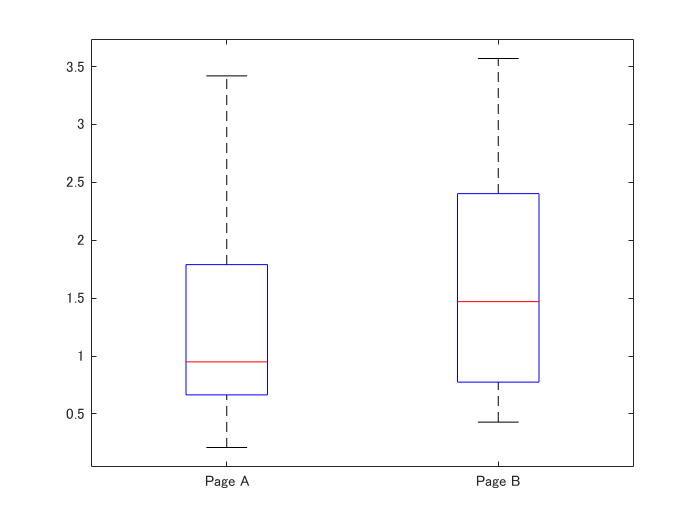

webpage = readtable("../psds_data/web_page_data.csv");
boxplot(webpage.Time,webpage.Page)

グループでの平均時間は次の形で計算ができます。

mean_a = mean(session_times{strcmp(session_times.Page, 'Page A'), 'Time'});
mean_b = mean(session_times{strcmp(session_times.Page, 'Page B'), 'Time'});
diff_meanab = mean_b - mean_a;

ページBの平均時間が、ページAよりも35.67秒長いことが分かりました。

次に並べ替え検定を行います。並べ替え検定には、繰り返しシャッフルして36セッション時間を21のグループ（ページAでn=21）と、15のグループ（ページBでn=15）の2つに分けます。

まず、n2個の被復元抽出した標本をグループBに割り当て、残りのn1個をグループAに割り当てた上に、2つのグループの平均の差を返すperm_func関数を作成します。

※スクリプト内に関数定義をする場合は、ファイルの最後に記述する必要があります。

この関数をR=1,000回、n2=15、n1=21として呼び出し、セッション時間の差の分布をヒストグラムとして表示します。

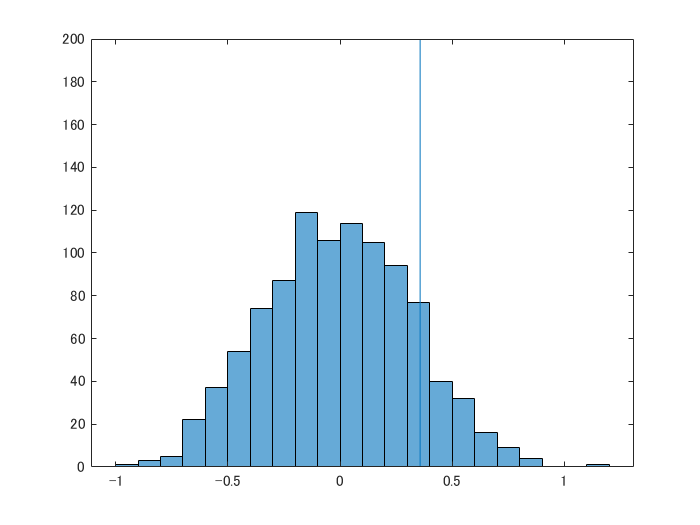

perm_diffs = zeros(1000, 1);
for i = 1:1000
    perm_diffs(i) = perm_func(session_times.Time, 21, 15);
end
histogram(perm_diffs);
line([diff_meanab, diff_meanab], [0, 200]);

## 3.4 :統計的優位性とp値 

価格A、価格Bの顧客転換率を無作為に並べ替えた場合の差のヒストグラムを作ります。

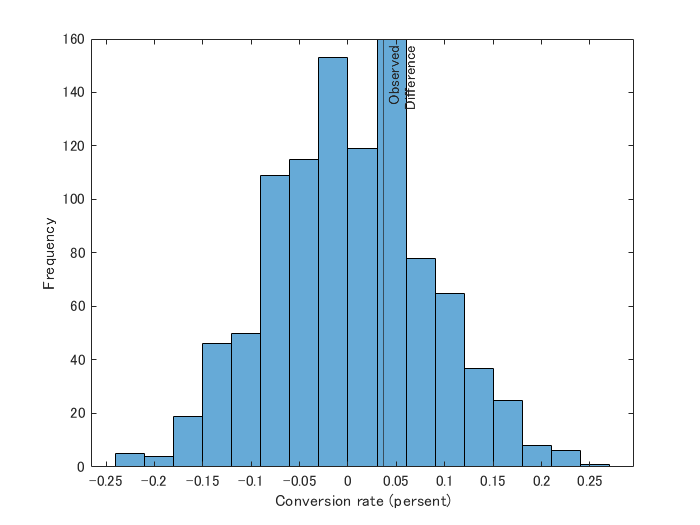

obs_pct_diff = 100*(200/23739 - 182/22588);
conversion = vertcat(zeros(45945,1),repelem(1,382,1));
perm_diffs = zeros(1000,1);
for i = 1:1000
    perm_diffs(i) = 100*perm_func(conversion, 23739, 22588);
end
histogram(perm_diffs);
xlabel('Conversion rate (persent)') ;
ylabel('Frequency') ;
xline(obs_pct_diff, '-' ,{'Observed','Difference'});

価格AとBのの顧客転換率の差の度数分布がでました（本書にはページAとBと書かれていますが、おそらく価格が正しいかと・・・）。

## 3.4.1 p値

並べ替え検定によって観測された最上の差が生じる時間割合を求めます。

mean(perm_diffs > obs_pct_diff)

ans = 0.3440

p値は0.339とでました。30％を超える確率で同じ結果が得られると期待できることを意味します。

本書ではRのprop.test関数を利用していますが、MATLABでは有志が作成されたprop_test関数（[doc](https://jp.mathworks.com/matlabcentral/fileexchange/45966-compare-two-proportions-chi-square)）を使用します。関数の利用方法については[こちら](https://jp.mathworks.com/help/matlab/ref/function.html)に掲載されています。

[h,p, chi2stat,df] = prop_test([200 182] , [23739 22588], true) %#ok<ASGLU> 

h = 0

p = 0.6996

chi2stat = 0.1489

df = 1

p値は0.6996とでました。。

## 3.5 :t検定

MATLABでt検定を行い場合にはttest関数（[doc](https://jp.mathworks.com/help/stats/ttest2.html)）を使用します。

x=session_times{strcmp(session_times.Page, 'Page A'), 'Time'} ;
y=session_times{strcmp(session_times.Page, 'Page B'), 'Time'} ;
[h,p,ci,stats] = ttest2(x, y, 'Tail','left') %#ok<ASGLU> 

h = 0

p = 0.1345

ci =       -Inf
    0.1800


stats = フィールドをもつ struct :
    tstat: -1.1237
       df: 34
       sd: 0.9389


## 3.8 :ANOVA

A/Bテストの代わりに、A-B-C-Dという複数の数値データの比較します。グループ間での統計的有意性を検定する統計手続きは、分散分析、あるいは ANOVAと呼ばれます。

4つのページの場合の比較を行います。まず、4つのグループの平均に対する箱ひげ図を出します。

foursessions = readtable("../psds_data/four_sessions.csv");
boxplot(foursessions.Time,foursessions.Page);

## 3.8.1 :F統計量

MATLABではanova1（[doc](https://jp.mathworks.com/help/stats/anova1.html)）でANOVA表を作成できます。

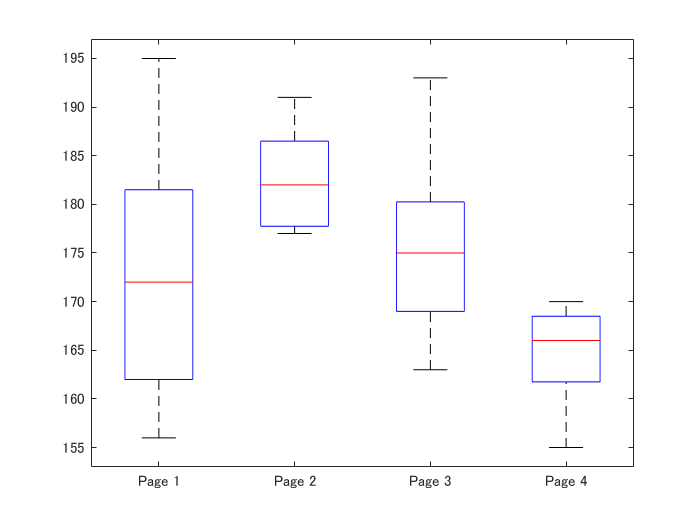

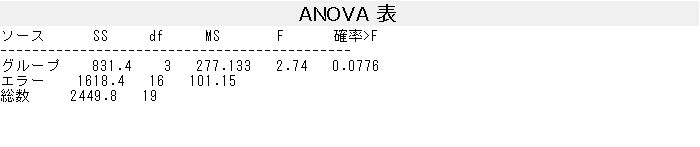

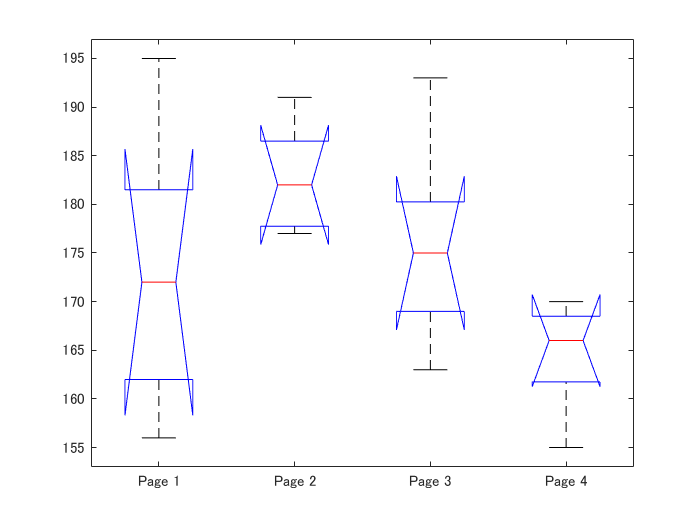

[p,tbl] = anova1(foursessions.Time,foursessions.Page); %#ok<ASGLU> 

## 3.9.2 :カイ二乗検定：統計理論

Rの chisq.test は集計後の数字を入力する仕様となっています。MATLABでカイ二乗検定を行う際に使用する chi2gof は集約前のデータを使用します。なので、集約されたデータを加工し、`chi2stat関数（`[doc](https://jp.mathworks.com/help/stats/chi2stat.html)`）で計算します。`

n1 = 14; N1 = 986;
n2 = 8; N2 = 992;
n3 = 12; N3 = 988;
x1 = [repmat('a',n1+N1,1); repmat('b',n2+N2,1) ; repmat('c',n3+N3,1)];
x2 = [ones(n1,1); 2*ones(N1,1); ones(n2,1); 2*ones(N2,1);  ones(n3,1); 2*ones(N3,1)];
[tbl,chi2stat,pval] = crosstab(x1,x2)

tbl =     14   986
     8   992
    12   988


chi2stat = 1.6659

pval = 0.4348

## 3.9.3 :フィッシャーの正確確率検定

有志が作成されたmyfisher23を使用します。

myfisher23関数の詳細は以下ですが、[こちら](https://jp.mathworks.com/matlabcentral/fileexchange/15399-myfisher23)から直接ダウンロードして使用することが可能です。

clickrates = readtable("../psds_data/click_rates.csv");
clicks = reshape(clickrates.Rate,2,3); 
myfisher23(clicks)

--------------------------------------------------------------------------------
2x3 matrix Fisher's exact test
--------------------------------------------------------------------------------
    Tables    two_tails_p_value    Mid_p_correction
    ______    _________________    ________________

     630           0.48241             0.44554     



結果はこちら。p値が0.4824と出ました。

## **3.11.1 サンプルサイズ**

MATLABでは`sampsizepwr関数が`、標本サイズまたは検出力を計算します。または、この 2 つの値が与えられた場合に仮説検定の対立仮説のパラメーター値を計算します。たとえば、対立仮説のパラメーター値が与えられた場合に、ある仮説検定について特定の検出力を取得するために必要な標本サイズを計算できま